clear all; clc
rng(123)
%%{
t = linspace(1,50,200);
V{1} = [sin(2*pi*t/50)', sin(2*pi*t/25)'];
V{2} = V{1}(1:2:end,:);
V{3} = V{1}(1:3:end,:);
To = cpdgen(V);
% To=To+0.2*rand(size(To));
%}
% T=reshape(1:2400, 10, 12, 20);
[Tm,~,~] =  give_miss_3(To, 0.15);
% figure(1); surf3(Tm);

T = reshape(Tm, 10,20,10,10,67);
szeT = size(T);
d=ndims(T); 
Cores=cell(1,d);
W=~isnan(squeeze(T(:,:,:,:,1))); 
ranks = [1,3,3,3,3,1];
%% Last Core
[Cores{d}, Tr] = CoreN(T, W, ranks(d));

%% First core
n=1; 
Wn=W;
Tmr = Tr;
sze=size(Tmr);
%------------------------
notn = [1:n-1 n+1:d-1]

notn =      2     3     4


Tn = permute(Tmr, [notn n d]);
Tn = reshape(Tn, [prod(sze(notn)) sze(n) sze(d)]);
Wn = permute(Wn, [notn n]);
Wn = reshape(Wn, [prod(sze(notn)) sze(n)]);
[cr] = grid_complete(Tn, Wn, ranks(n+1));
Cores{n} = reshape(cr, [1, size(cr)])

Cores = 1×5 cell array
    {1×10×2 double}    {0×0 double}    {0×0 double}    {0×0 double}    {2×67 double}


%2nd-core
Tmr = tmprod(rep0(Tmr),cr.', 1);
Tmr(Tmr==0)=NaN;
sze=size(Tmr)

sze =      2    20    10    10     2


s12 = prod(sze(1:2));
sze(1:2)=[];
sze = [s12 sze];
Tmr = reshape(Tmr, sze);

%% n-th core
n=1; 
i=1;
W = ~isnan(Tmr(:,:,:,1));
Wn=W;
sze=size(Tmr);
d = ndims(Tmr);
%------------------------
notn = [1:n-1 n+1:d-1]

notn =      2     3


Tn = permute(Tmr, [notn n d]);
Tn = reshape(Tn, [prod(sze(notn)) sze(n) sze(d)]);
Wn = permute(Wn, [notn n]);
Wn = reshape(Wn, [prod(sze(notn)) sze(n)]);
[cr] = grid_complete(Tn, Wn, ranks(n+i+1));
Cores{n+i} = reshape(cr,ranks(n+i), szeT(n+i), ranks(n+i+1))

Cores = 1×5 cell array
    {1×10×2 double}    {2×20×2 double}    {0×0 double}    {0×0 double}    {2×67 double}


% 3rd core
Tmr = tmprod(rep0(Tmr),cr.', 1);
Tmr(Tmr==0)=NaN;
sze=size(Tmr)

sze =      2    10    10     2


s12 = prod(sze(1:2));
sze(1:2)=[];
sze = [s12 sze];
Tmr = reshape(Tmr, sze);

%% n-th core
n=1; 
i=2;
W = ~isnan(Tmr(:,:,1));
Wn=W;
sze=size(Tmr);
d = ndims(Tmr);
%------------------------
notn = [1:n-1 n+1:d-1]

notn = 2

Tn = permute(Tmr, [notn n d]);
Tn = reshape(Tn, [prod(sze(notn)) sze(n) sze(d)]);
Wn = permute(Wn, [notn n]);
Wn = reshape(Wn, [prod(sze(notn)) sze(n)]);
[cr] = grid_complete(Tn, Wn, ranks(n+i+1));
Cores{n+i} = reshape(cr,ranks(n+i), szeT(n+i), ranks(n+i+1))

Cores = 1×5 cell array
    {1×10×2 double}    {2×20×2 double}    {2×10×2 double}    {0×0 double}    {2×67 double}


% 4-th core
i=3

i = 3

Tmr = tmprod(rep0(Tmr),cr.', 1);
Tmr(Tmr==0)=NaN;
sze=size(Tmr)

sze =      2    10     2


s12 = prod(sze(1:2));
sze(1:2)=[];
sze = [s12 sze];
Tmr = reshape(Tmr, sze);
Cores{n+i} = reshape(Tmr,ranks(n+i), szeT(n+i), ranks(n+i+1))

Cores = 1×5 cell array
    {1×10×2 double}    {2×20×2 double}    {2×10×2 double}    {2×10×2 double}    {2×67 double}


[G_nl,G_nr]=G_nmode_devide(Cores,4);
GL_m = reshape(G_nl, [], ranks(4));
GR_m = reshape(G_nr, ranks(4+1), []);

FME = kron(GR_m', eye(szeT(4))); %I_n: size(sze(n)); Frame matrix 
FME = kron(FME, GL_m);

tol=1e-4;
maxit=5;
x0 = reshape(Cores{4}, [],1);
b_known = reshape(Tm,[], 1);  % missing values as nan in this vector

%tic
[core_mid_opt,~, ~,~] = solve_LS_miss(FME, b_known, x0, tol, maxit);

   7.7646e-16



%toc

Cores{4} = reshape(core_mid_opt, size(Cores{4}));

Unrecognized function or variable 'G'.

% sze = size(T);
% ranks = [1,3,3,3,3,1]

ranks =      1     3     3     3     3     1


% Go = initcoreten(szeT,ranks(2:end-1));
% [G] = TT_Cpl(Tm, Go, sze, ranks);

   1.5847e-15

   1.7993e-05

   4.6625e-10

   6.0145e-14

   3.1981e-05

   6.5309e-06



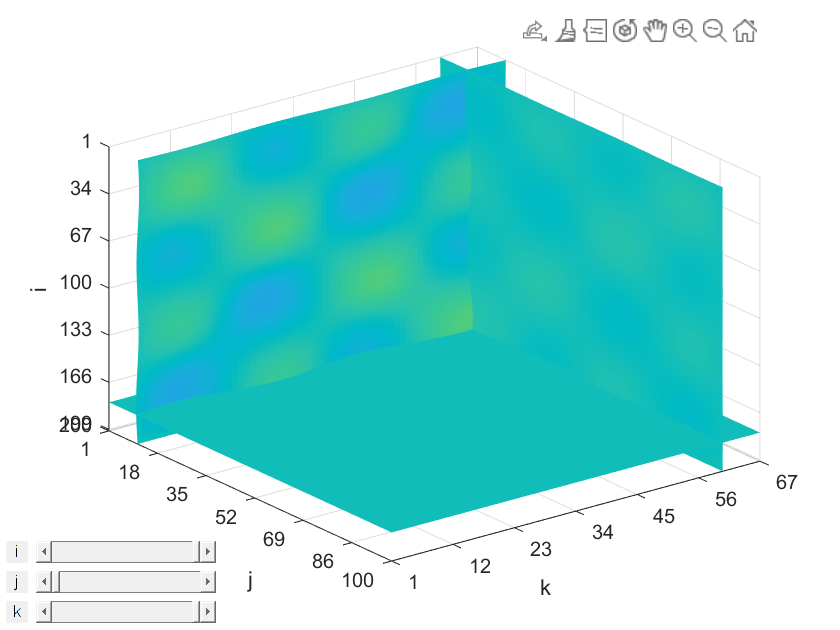

% Trex = TT_Full(G);
% Trex = reshape(Trex, size(Tm));
% figure(990)
% surf3(Trex)

## Using MLSVD

T = reshape(Tm, 10,20,10,10,67);
szeT = size(T);
d=ndims(T); 
Cores=cell(1,d);
W=~isnan(squeeze(T(:,:,:,:,1))); 
R=[2 2 2 2 2]

R =      2     2     2     2     2


[Uml, Sml] = mlsvd_fs(T, W, R);

Trx = lmlragen(Uml, Sml);

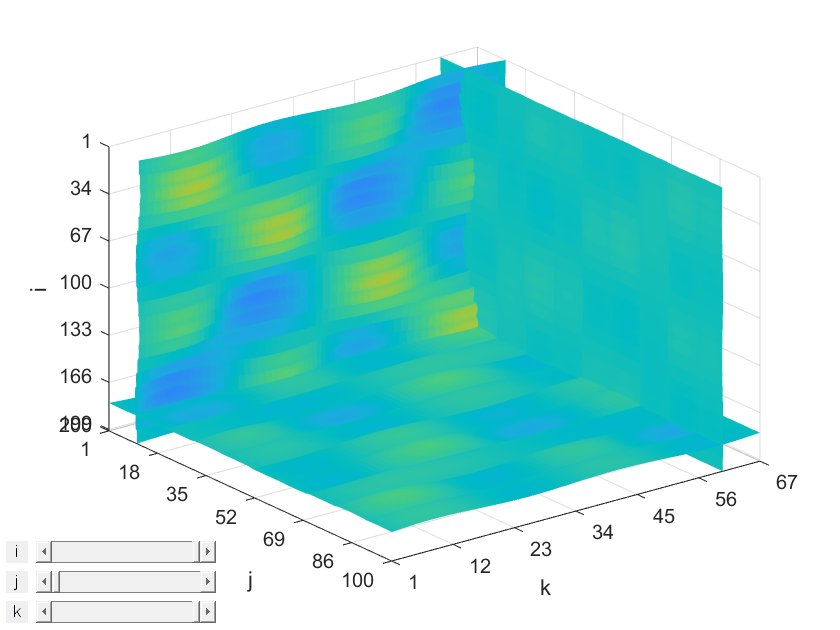

Trx = reshape(Trx, size(Tm));
figure(999)
surf3(Trx)

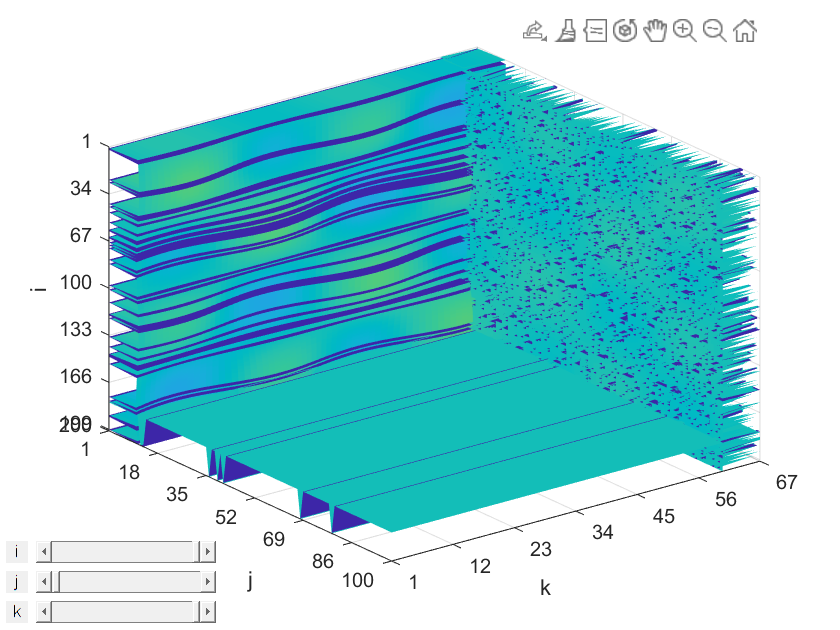

Trxo = reshape(T, size(Tm));
figure(100)
surf3(Trxo)